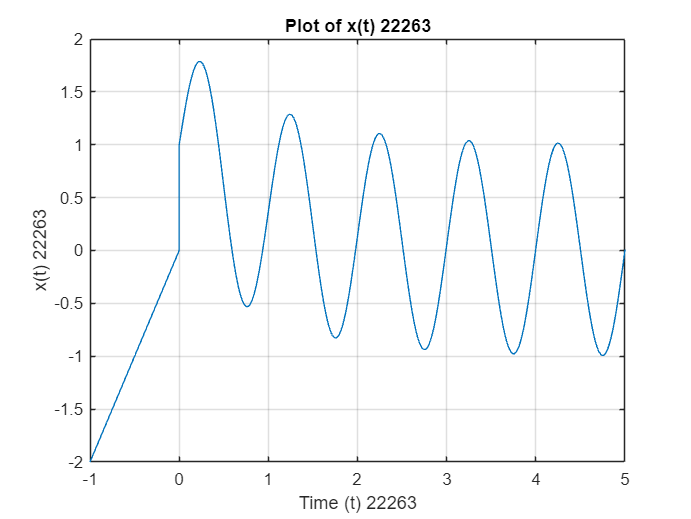

% Define the time vectors
t1_22263 = linspace(-1, 0, 500); % For 2t
t2_22263 = linspace(0, 5, 1000); % For e^(-t) + sin(2*pi*t)
t_22263 = [t1_22263, t2_22263]; % Combine and avoid duplicating t=0

% Define x(t)
x1_22263 = 2*t1_22263;
x2_22263 = exp(-t2_22263) + sin(2*pi*t2_22263);
x_22263 = [x1_22263, x2_22263]; % Combine

% Plot x(t)
figure;
plot(t_22263, x_22263);
xlabel('Time (t) 22263');
ylabel('x(t) 22263');
title('Plot of x(t) 22263');
grid on;

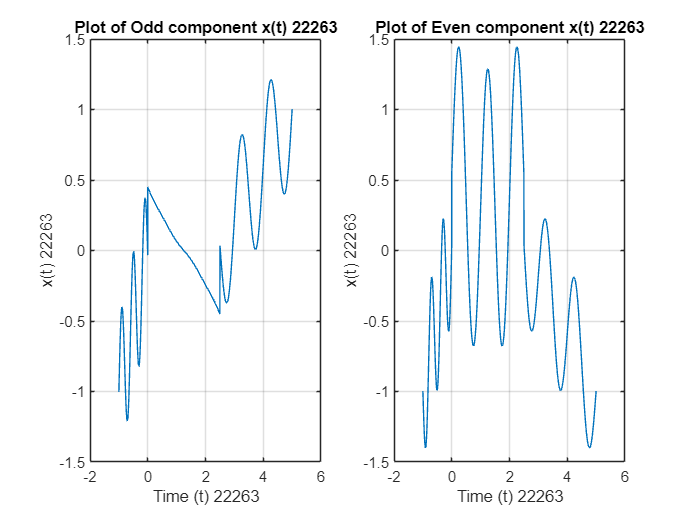


% Define the modified time vector and compute x(0.5t + 0.5)
%t_mod_22263 = 0.5*t_22263 + 0.5;
%x_mod_22263 = interp1(t_22263, x_22263, t_mod_22263, 'linear', 'extrap'); % Interpolate x at modified time points

% % Plot x(0.5t + 0.5)
% figure;
% plot(t_22263, x_mod_22263);
% xlabel('Time (t) 22263');
% ylabel('x(0.5t + 0.5) 22263');
% title('Plot of x(0.5t + 0.5) 22263');
% grid on;

%Plotting Even and Odd Components
x_odd_22263=(x_22263-fliplr(x_22263))/2;
x_even_22263=(x_22263+fliplr(x_22263))/2;

figure;
subplot(1,2,1)
plot(t_22263,x_odd_22263);
xlabel('Time (t) 22263');
ylabel('x(t) 22263');
title('Plot of Odd component x(t) 22263');
grid on;
hold on;

subplot(1,2,2)
plot(t_22263,x_even_22263);
xlabel('Time (t) 22263');
ylabel('x(t) 22263');
title('Plot of Even component x(t) 22263');
grid on;
hold off;